% Symbolic solution of a 5X5 RC ladder (N=5).  All five resistors have 
% value R/N=200 Ohm (i.e. R=1k Ohm) and the capacitors have values 
% NC=55.555fF and 3NC=166.665fF (i.e. C = 11.111fF)..
%
syms s t; % Create symbolic variables "s" and "t".
%
% Enter the ladder circuit's s-domain node-voltage matrix:
%
% [N/R + sNC + N/R       -N/R               0                 0              0
%      -N/R          N/R + sNC +N/R       -N/R                0              0
%        0               -N/R         N/R + sNC + N/R       -N/R             0
%        0                 0              -N/R         N/R + sNC + N/R     -N/R
%        0                 0                0               -N/R         N/R + s3NC]
%
A=sym([1e-2+s*55.555e-15, -5e-3,               0,         0,                    0
      -5e-3,               1e-2+s*55.555e-15, -5e-3,      0,                    0
       0,                 -5e-3,     1e-2+s*55.555e-15,  -5e-3                  0
       0,                  0,                 -5e-3,      1e-2+s*55.555e-15,   -5e-3
       0,                  0,                  0,        -5e-3,         5e-3+s*166.665e-15]);
%
% Enter column vector for initial-condition impulse current sources:
% All capacitors have V(0)=5V.
%
% [NC*5V
%  NC*5V
%  NC*5V
%  NC*5V
%  3NC*5V]
%
B = sym([55.555e-15*5
         55.555e-15*5
         55.555e-15*5
         55.555e-15*5
         166.665e-15*5]);
%
V = A\B; % This is the s-domain solution vector for V1, V2, V3, V4 and 
% V5=Vout.
Vs = vpa(V,3); % Variable precision arithmetic, 3 decimal places.
Vs % Display the s-domain answer to 3 significant digits.

$$Vs = \begin{array}{l} \left(\begin{array}{c} \frac{1.1\,10^{18}\,\left(\sigma_{2}+1.16\,10^{81}\,s^{3}+2.42\,10^{92}\,s^{2}+1.71\,10^{103}\,s+2.69\,10^{113}\right)}{\sigma_{1}}\\ \frac{1.1\,10^{18}\,\left(\sigma_{2}+\sigma_{3}+3.18\,10^{92}\,s^{2}+2.65\,10^{103}\,s+5.0\,10^{113}\right)}{\sigma_{1}}\\ \frac{1.1\,10^{18}\,\left(\sigma_{2}+\sigma_{3}+\sigma_{4}+3.08\,10^{103}\,s+6.93\,10^{113}\right)}{\sigma_{1}}\\ \frac{1.1\,10^{18}\,\left(\sigma_{2}+\sigma_{3}+\sigma_{4}+3.21\,10^{103}\,s+8.47\,10^{113}\right)}{\sigma_{1}}\\ \frac{6.88\,10^{18}\,\left(2.81\,10^{68}\,s^{4}+2.11\,10^{80}\,s^{3}+5.32\,10^{91}\,s^{2}+5.13\,10^{102}\,s+1.54\,10^{113}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3.87\,10^{86}\,s^{5}+2.9\,10^{98}\,s^{4}+7.32\,10^{109}\,s^{3}+7.06\,10^{120}\,s^{2}+2.12\,10^{131}\,s+7.62\,10^{140}\\ \sigma_{2}=1.76\,10^{69}\,s^{4}\\ \sigma_{3}=1.32\,10^{81}\,s^{3}\\ \sigma_{4}=3.33\,10^{92}\,s^{2} \end{array}$$

%
v = ilaplace(V); % This is the time domain solution vector for v1, v2, v3,
% v4 and v5 = vout.
vt = vpa(v,3); % Variable precision arithmetic.
vt % Display the t-domain answer to 3 significant digits. Note:

$$vt = \begin{array}{l} \left(\begin{array}{c} 0.18\,\sigma_{5}+1.55\,\sigma_{3}+0.645\,\sigma_{2}+1.42\,\sigma_{4}+1.2\,\sigma_{1}\\ 2.33\,\sigma_{3}-0.293\,\sigma_{5}-0.433\,\sigma_{2}+2.78\,\sigma_{4}+0.624\,\sigma_{1}\\ 0.299\,\sigma_{5}+1.93\,\sigma_{3}-0.355\,\sigma_{2}+4.0\,\sigma_{4}-0.875\,\sigma_{1}\\ 0.558\,\sigma_{3}-0.195\,\sigma_{5}+0.671\,\sigma_{2}+5.05\,\sigma_{4}-1.08\,\sigma_{1}\\ 0.0197\,\sigma_{5}-1.09\,\sigma_{3}-0.0957\,\sigma_{2}+5.86\,\sigma_{4}+0.314\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-1.33\,10^{11}\,t}\\ \sigma_{2}={\mathrm{e}}^{-2.4\,10^{11}\,t}\\ \sigma_{3}={\mathrm{e}}^{-4.53\,10^{10}\,t}\\ \sigma_{4}={\mathrm{e}}^{-4.15\,10^{9}\,t}\\ \sigma_{5}={\mathrm{e}}^{-3.27\,10^{11}\,t} \end{array}$$

% numerical limitations result in small imaginary terms appearing in the 
% solution. These are ingnored by ezplot.
%
delay = vpasolve(v(5)==2.5,t,0.5e-9); % Solves for the propagation delay
% corresponding to vout(t=tp) = 2.5V.  Initial guess is 0.5ns.
format short eng
figure(3)
tp = double(delay); % Convert symbolic result to numeric value for display.
ezplot(vpa(v(5),3),[0, 1e-9]) % Plot vout(t) for t = 0 to 1ns.
ylim([0 5.2])
xlabel('t (s)')
ylabel('V_{out}  (V)')
hold

Current plot held


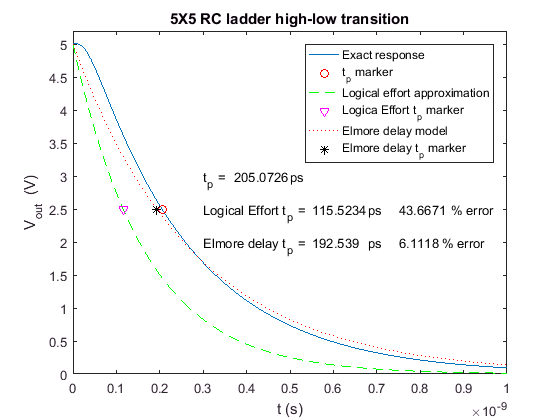

plot(tp,2.5,'ro'); % Mark vout at tp.
title('5X5 RC ladder high-low transition')
%grid ON
tt = 0:1e-11:1e-9; % Time points for first-order (logical effort) delay.
% R3NC = 1e3*166.665E-15 = 166.665e-12.
VRC = 5*exp(-tt/166.665e-12); %Simple first-order (logical effort) response.
plot(tt,VRC,'g--')
LEtp = log(2)*166.665e-12; % 1st-order tp is ln(2)*R3NC = 0.69*R3NC.
plot(LEtp,2.5,'mv') % Mark 1st-order (logical effort) tp.
%
% Elmore delay model: R = 1e3, C = 11.111e-15, N = 5.
Etau = 0.5*1e3*11.111e-15*(5^2 + 5*5); % 1/2*RC(N^2 + 5N). 
VElmore = 5*exp(-tt/Etau);
plot(tt,VElmore,'r:')
EMtp = log(2)*Etau; % Elmore tp is ln(2)*Etau = 0.69*Etau.
plot(EMtp,2.5,'k*')
legend('Exact response','t_{p} marker','Logical effort approximation',...
       'Logica Effort t_{p} marker','Elmore delay model',...
       'Elmore delay t_{p} marker', 'Location','NorthEast')
%
LEerror = 100*(tp-LEtp)/tp; % Percent error in logical effort delay.
EMerror = 100*(tp-EMtp)/tp; % Percent error in Elmore model delay.
% Annotate plot:
text(3e-10,2.95,'t_{p} = ')
text(3.7e-10,3,num2str(tp*1e12))
text(5e-10,3,'ps')
text(3e-10,2.45,'Logical Effort t_{p} = ')
text(5.5e-10,2.5,num2str(LEtp*1e12))
text(6.8e-10,2.5,'ps')
text(7.5e-10,2.5,num2str(LEerror))
text(8.7e-10,2.5,'% error')
text(3e-10,1.95,'Elmore delay t_{p} = ')
text(5.5e-10,2,num2str(EMtp*1e12))
text(6.8e-10,2,'ps')
text(8.5e-10,2,'% error')
text(7.5e-10,2,num2str(EMerror))